directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder";
cd(directory);      % Arbeitsverzeichnis setzen

imdsSchilder = imageDatastore(directory, "IncludeSubfolders", true, "LabelSource", "foldernames");

outputFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bildermit rahmen";

% a= exist(outputFolder, 'dir')
% 
% if a==0;
%     mkdir(outputFolder);
% end
% % 
% Jedes Bild durchlaufen, in Grau umwandeln und speichern
% for i = 1:numel(imdsSchilder.Files)
%     img = imread(imdsSchilder.Files{i});    % Bild laden
%     grayImg = rgb2gray(img);        % In Grau konvertieren
%     [~, filename, ext] = fileparts(imdsSchilder.Files{i}); % Dateiname extrahieren
%     imwrite(grayImg, fullfile(outputFolder, [filename, '_gray', ext])); % Speichern
% end
% imdsSchilderGrau = imageDatastore(outputFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

Test Kreiserkennung

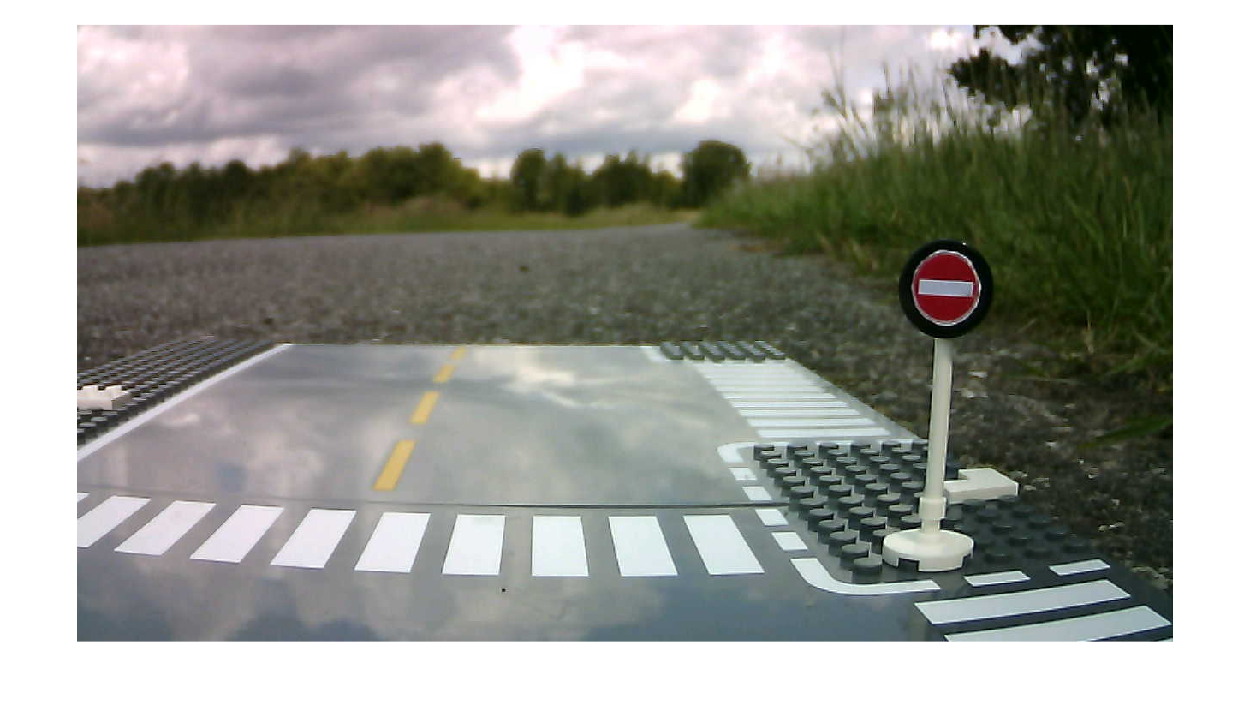

General Error occurred in WebControllerFactory::create()


dataArray = [];
filename = 'meineDaten.txt';
for i = 1:numel(imdsSchilder.Files)
    I = imread(imdsSchilder.Files{i});    % Bild laden
    imshow(I);
    % eintragen der Bilddatei in excel
    Pfadschild = imdsSchilder.Files{i};
    writematrix(string(Pfadschild), filename, 'WriteMode', 'append');
    [centers, radii] = imfindcircles(I, [20, 200], 'Sensitivity', 0.92);
    viscircles(centers, radii,'EdgeColor','b');
    %eintragen der erkannten daten in excel
    newData = [centers,radii];
    writematrix(newData, filename,'WriteMode','append');
end

% In Excel schreiben


Grauebilder

% filename = 'meineDatenGrau.txt';
% dataArrayGray = [];
% for i = 1:numel(imdsSchilderGrau.Files)
%     %eintragen der Bilddatei in excel
%     grayImage = imread(imdsSchilderGrau.Files{i});    % Bild laden
%     Pfadschild=imdsSchilderGrau.Files{i}
%     writematrix(Pfadschild, filename,'WriteMode','append');
%     imshow(grayImage);
%     [centers, radii] = imfindcircles(grayImage, [15, 200], 'Sensitivity', 0.9)
%     viscircles(centers, radii,'EdgeColor','b');
%     %eintragen der erkannten daten in excel
%     newData = [centers,radii];
%     writematrix(newData, filename,'WriteMode','append');
% end
